A = [1 -4; -7 -5];
b = [0; 2];
C = [1 0];
tn = 1.2;
sigma = 0;

rank([b A*b])

ans = 2

rank([C*b C*A*b])

ans = 1

rank([C;C*A])

ans = 2

rank([C*b;C*A*b])

ans = 1

Ad = [0 1; -15.6684 -7.9167];
H = [1 0];

eig(Ad)

ans =    -3.9467
   -3.9700


M = sylvester(A, -Ad, b*H);
K = H*M^-1;

A0g = [0 1; -6 -9];
b0g = [0;1];
AM = A - b*K

AM =     1.0000   -4.0000
    6.1463   -8.9167


eig(AM)

ans =    -3.9467
   -3.9700


syms s
C*inv(s*eye(2)-AM)*b

$$ans = -\frac{351843720888320000}{43980465111040000\,s^{2}+348180148144570368\,s+689103519545819007}$$

gamma = 1000;
Tmdl = 100;

warning off
SimNew = sim('model_2022b1.slx','ReturnWorkspaceOutputs', 'on');
warning on

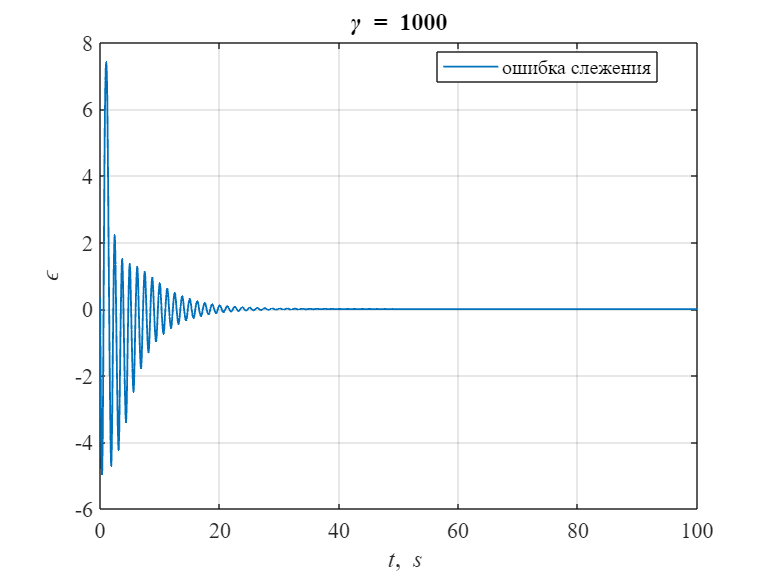

t = SimNew.out.time;
eps = SimNew.out.signals(1).values;
u = SimNew.out.signals(2).values;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,eps,'LineWidth',1)
hold on
grid on
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\epsilon')
legend('ошибка слежения','Location','best')
title('\gamma = 1000')

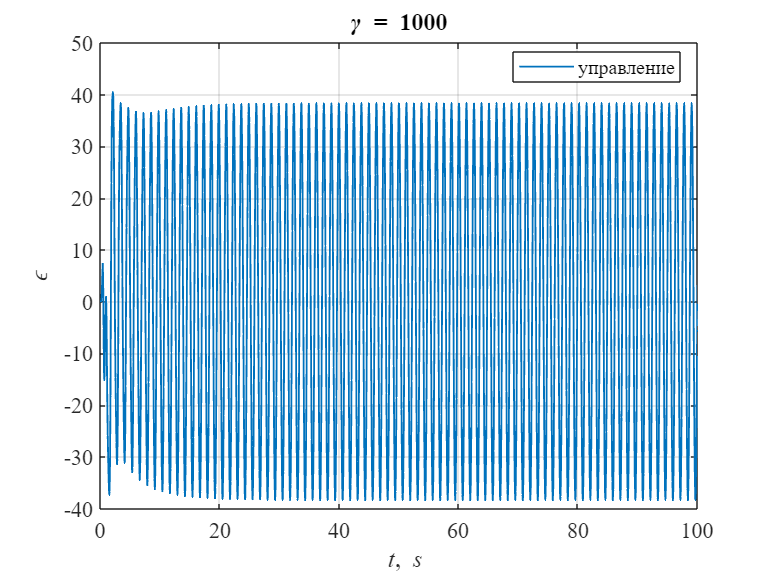

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,u,'LineWidth',1)
hold on
grid on
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\epsilon')
legend('управление','Location','best')
title('\gamma = 1000')

gamma = 10;
Tmdl = 1000;

warning off
SimNew = sim('model_2022b1.slx','ReturnWorkspaceOutputs', 'on');
warning on

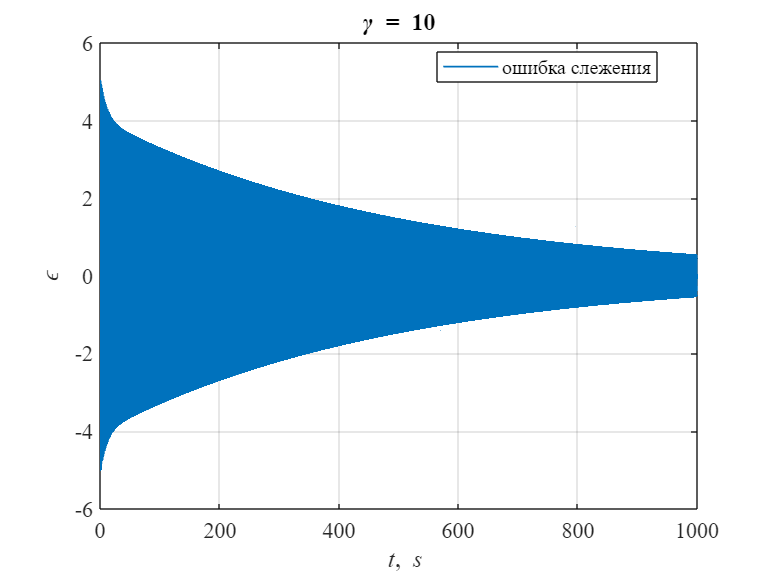

t = SimNew.out.time;
eps = SimNew.out.signals(1).values;
u = SimNew.out.signals(2).values;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,eps,'LineWidth',1)
hold on
grid on
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\epsilon')
legend('ошибка слежения','Location','best')
title('\gamma = 10')

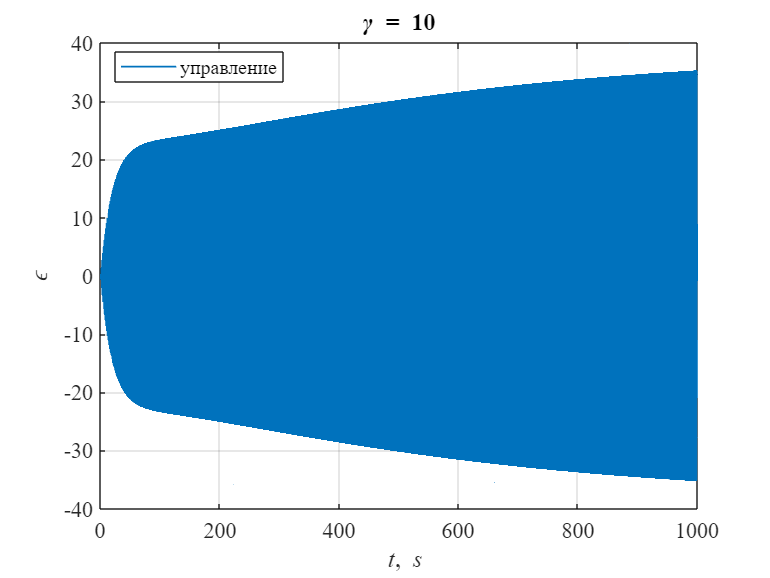

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,u,'LineWidth',1)
hold on
grid on
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\epsilon')
legend('управление','Location','best')
title('\gamma = 10')